## TOPIC 3: Systems of equations, functions, and more

ENGR105, 9/10/20

### Array mathematics (continued)

#### Addition and Subtraction

General rules for addition and subtraction for arrays of any dimension (e.g. vectors or matrices)

- Scalars may be added to/subtracted from any array -** the scalar value is added to all elements of the array**

- Arrays added to arrays must have the **same dimensions** and elements in correlated index locations can be added or subtracted. 

Remember: matrix dimensions must agree. In other words, the matrices must have the same dimensions.

#### Multiplication

General rules for matrix/array multiplication:

- Arrays may be multiplied by a **scalar**.

- **Arrays of the same dimensions** may be multiplied index-by-index using the array multiplier/vectorization (`.*`)

- The matrix product (`*`) may be evaluated for matrices if the "inner dimensions" of the original matrices match and the resulting matrix will have dimensions equal to the outer dimensions of the matrices being multiplied.

**Case 1: multiplication by a scalar**

% Create same matrices as last time
A = [1,5;2,3]

A =      1     5
     2     3


B = [A(2,:);A(1,:)]

B =      2     3
     1     5


A

A =      1     5
     2     3


A*5

ans =      5    25
    10    15


**Case 2: element-by-element multiplication**. Arrays of the same dimensions may be multiplied index-by-index using the array multiplier/vectorization (.*)

A

A =      1     5
     2     3


B

B =      2     3
     1     5


A.*B

ans =      2    15
     2    15


**Case 3: matrix multiplication**. For `A*B`, the **columns of A must equal the rows of B**.

The element in the first row and first column of `A*B` is:

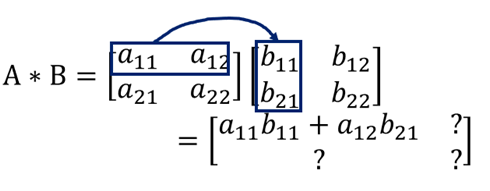

The element in the first row and second column of `A*B` is:

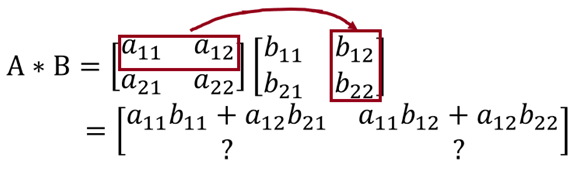

Filling in the matrix:

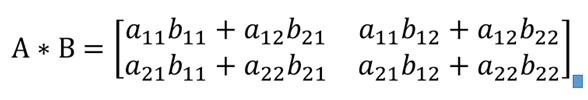

A = [1,4;2,3];
B = [1,2;3,4];
% Matrix multiplication
A*B

ans =     13    18
    11    16


**Remember: A*B is not usually the same as B*A**

% Matrix multiplication with multiplication order reversed.
B*A

ans =      5    10
    11    24


**Pro tip:** if you feel stressed about this, write out each entry systematically! You will work a lot more with matrices in your linear algebra courses.

**Remember**: the dimensions of the matrix product are equal to the outer dimensions of the original matrices and the inner dimensions must match

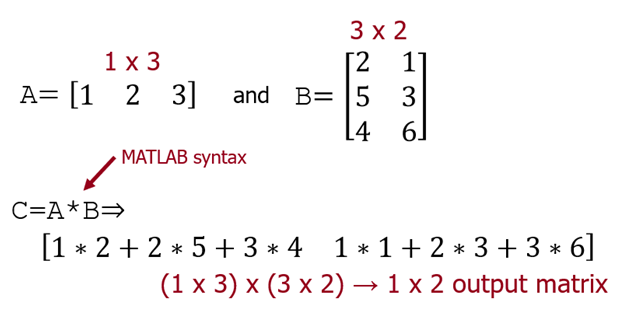

B = [2,1;5,3;4,6]

B =      2     1
     5     3
     4     6


A = 1:3

A =      1     2     3


% To perform matrix multiplication, ensure the columns of the first matrix
% match the rows of the second
A*B

ans =     24    25


#### Division

**Division of a scalar by an array** necessitates an array operator. 

A = [1 2; 4 8]

A =      1     2
     4     8


B = 16./A

B =     16     8
     4     2


**NOTE**: `B = 16/A` will return an error.

**NOTE**: Matrix division has a different interpretation than scalar division. Right division is different than left division.

**Element-wise division:**

- *Right* division: `A./B` is equivalent to `A(i,j)/B(i,j)` 

- *Left* division:  `A.\B` is equivalent to `B(i,j)/A(i,j) `

% Define matrix A and vector b
A = [2,4;2,6];
B = [1,2;1,3];
% Perform right division
A./B

ans =      2     2
     2     2


% Perform left division
A.\B

ans =     0.5000    0.5000
    0.5000    0.5000


**Left matrix division**. Consider the following matrix equation, in which matrix **A** is multiplied by vector **x** to give vector **b**. 

            
$$\textrm{Ax}=\mathbf{b}$$


Note on dimensions: assuming A is square (e.g. `2x2`), then **x** and **b** must be (e.g. `2x1)` column vectors. To solve for **x**, you must perform left division of matrix **A**, or left multiply by the inverse of **A**.

            
$${\mathbf{x}=\mathbf{A}\backslash \textrm{Ax}=\mathbf{A}}^{-1} \textrm{Ax}=\mathbf{A}\backslash \mathbf{b}={\mathbf{A}}^{-1} \mathbf{b}$$


The above works because ${\mathbf{A}}^{-1} \mathbf{A}=\mathrm{I}$, where $\mathrm{I}$ is the identity matrix, and $\textrm{IX}=\mathbf{X}$ (by definition).

% Define matrix A and vector b
A = [2,4;2,6]

A =      2     4
     2     6


b = [5;4]

b =      5
     4


% Perform left division
A\b

ans =     3.5000
   -0.5000


inv(A)*b

ans =     3.5000
   -0.5000


**Right matrix division**. Consider the following matrix equation, in which matrix **A** is multiplied by vector **x** to give vector **b**. 

            
$$\textrm{xA}=\mathbf{b}$$


Note on dimensions: assuming A is square (e.g. `2x2`), then **x** and **b** must be (`e.g. 1x2`) row vectors. To solve for **x**, you must perform right division of matrix **A**, or right multiply by the inverse of **A**.

            
$${\mathbf{x}=\textrm{xA}/\mathbf{A}=\textrm{xAA}}^{-1} =\mathbf{b}/\mathbf{A}=\mathbf{b}{\mathbf{A}}^{-1}$$


A = [2,4;2,6]

A =      2     4
     2     6


b = [5,4]

b =      5     4


% Perform right division
b/A

ans =     5.5000   -3.0000


b*inv(A)

ans =     5.5000   -3.0000


### Application: solving a set of linear equations

You are likely familiar with canonical linear equations of the form `y=mx+b` or `ax+by=c`, which define a straight line in 2D space. Consider a set of two linear equations:

            
$$\begin{array}{l}
y=m_1 x+b_1 \\
y=m_2 x+b_2 
\end{array}$$


In engineering applications, you are often interested in solving a set of linear equations. There are three possibilities:

**There is one solution.**

              
$$\begin{array}{l}
y=x\\
y=2x-3
\end{array}$$


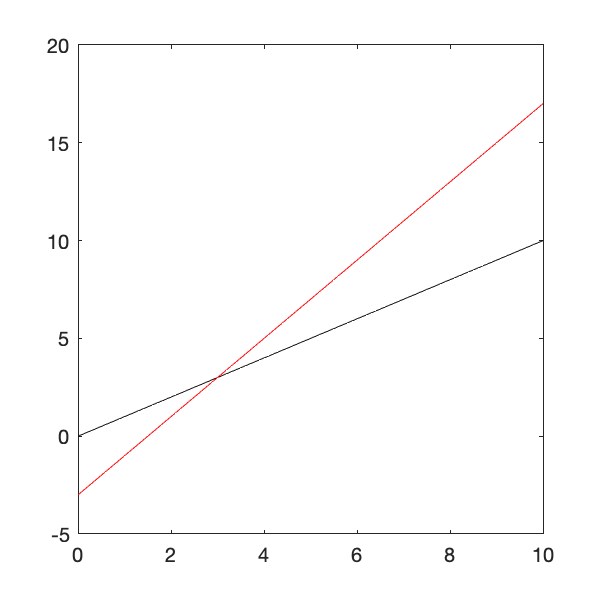

% x vectors
x = 0:.1:10;
% Create a figure window of a defined size
figure('Position',[0,0,300,300]);
plot(x,x,'k-',x,2*x-3,'r-')

**There are no solutions.**

              
$$\begin{array}{l}
y=x\\
y=x-3
\end{array}$$


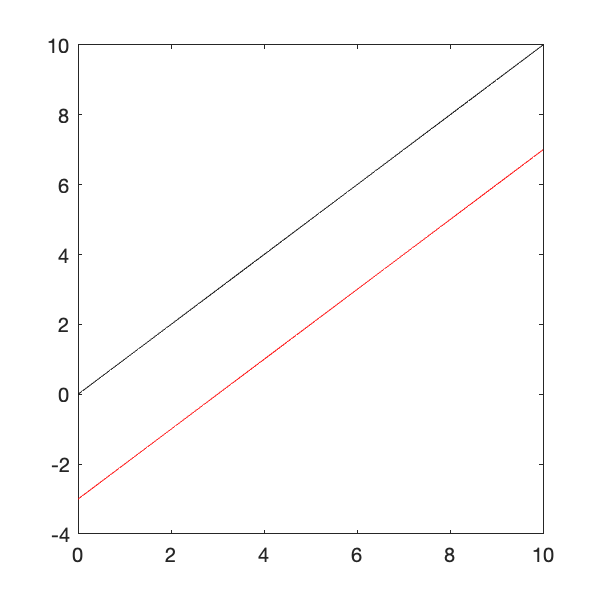

% Create a figure window of a defined size
figure('Position',[0,0,300,300]);
plot(x,x,'k-',x,x-3,'r-')

**There are infinite solutions.**

              
$$\begin{array}{l}
y=x\\
y=x
\end{array}$$


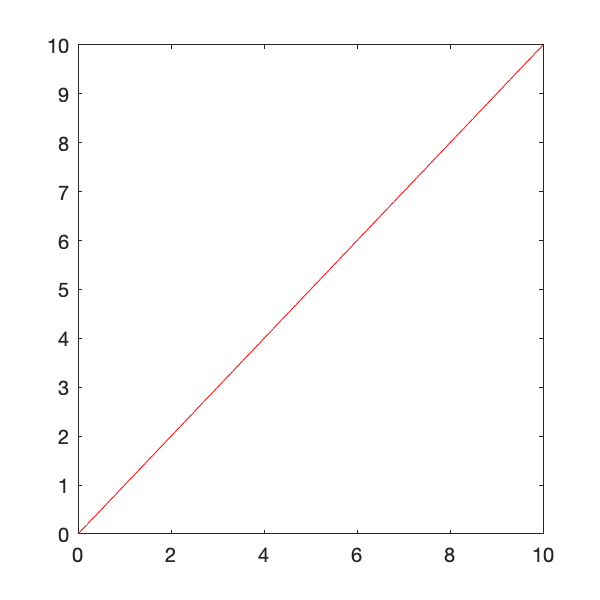

% Create a figure window of a defined size
figure('Position',[0,0,300,300]);
plot(x,x,'k-',x,x,'r-')

We will focus on systems that have one solution. Further study in linear algebra will provide conditions on matrix **A** and vector **b** that will enable you to determine the number of solutions.

#### One approach: substitution

Consider the two equations defined above. To solve, perform the following steps.

             
$$\begin{array}{l}
y=m_1 x+b_1 \\
y=m_2 x+b_2 
\end{array}$$


1) Set equations equal

             
$$m_1 x+b_1 =m_2 x+b_2$$


2) Solve for x

             
$$\begin{array}{l}
\left.x{\left(m\right.}_1 -m_2 \right)=b_2 -b_1 \\
x=\frac{\left(b_2 -b_1 \right)}{\left.{\left(m\right.}_1 -m_2 \right)}
\end{array}$$


3) Substitute to solve for y

             
$$y=m_1 \frac{\left(b_2 -b_1 \right)}{\left.{\left(m\right.}_1 -m_2 \right)}+b_1$$


This is fine, but requires equations in the above form and can get tedious.

#### Another approach: matrix representation

Rearranging the above system of equations:

                
$$\begin{array}{l}
y{-m}_1 x=b_1 \\
y-m_2 x=b_2 
\end{array}$$


Double check the matrix multiplication rules above. Based on the rules of matrix multiplication, the above set of equations can be represented in matrix form:

                
$$\left\lbrack \begin{array}{cc}
1 & {-m}_1 \\
1 & {-m}_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y\\
x
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
b_1 \\
b_2 
\end{array}\right\rbrack$$


Or:

                
$$\begin{array}{l}
\textrm{Ax}=\mathbf{b}\\
\mathbf{A}=\left\lbrack \begin{array}{cc}
1 & {-m}_1 \\
1 & {-m}_2 
\end{array}\right\rbrack \\
\mathbf{x}=\left\lbrack \begin{array}{c}
y\\
x
\end{array}\right\rbrack \\
\mathbf{b}=\left\lbrack \begin{array}{c}
b_1 \\
b_2 
\end{array}\right\rbrack 
\end{array}$$


This is the case above corresponding to **left matrix division**. Thus, we can simply solve for `y` and `x` by performing a left division:

                
$$\mathbf{x}=\mathbf{A}\backslash \textrm{Ax}=\mathbf{A}\backslash \mathbf{b}$$


**Example 1**. Solve the following system of equations. 

                
$$\begin{array}{l}
y=x\\
y=2x-3
\end{array}$$


% Step 1: convert to matrix format
A = [1,-1;1,-2] %Coefficient matrix defined above

A =      1    -1
     1    -2


b = [0;-3] % Constant matrix

b =      0
    -3


% Step 2: solve for x and y


Thus, the solution exists at `x = 3` and `y = 3`.

#### More general representation

More often, you will encounter systems with more than two variable. Thus, it is more convenient to think of a system of linear equations in the following form, where there are `n` variables and `n` equations.

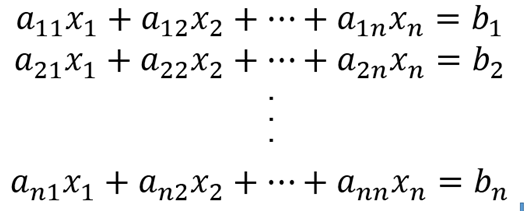

The above can be represented compactly in matrix form:

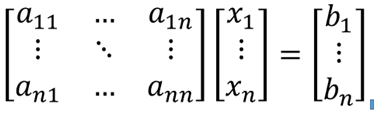

Or again as:

                
$$\textrm{Ax}=\mathbf{b}$$


**Note: matrix **`A`** is slightly different than defined previously. **This is a more general form.

**Example 2. **Solve the following system of equations.

                
$$\begin{array}{l}
x_1 +{3x}_2 +x_3 =1\\
{2x}_1 +{2x}_2 -x_3 =2\\
x_1 +x_2 +x_3 =-2
\end{array}$$


% Step 1: convert to matrix format
A = [1,3,1;2,2,-1;1,1,1]; %Coefficient matrix defined above
b = [1;2;-2]; % Constant matrix
% Step 2: solve for x 
x = A\b

x =    -1.5000
    1.5000
   -2.0000


Thus, the solution to this problem is $x_1 =-1\ldotp 5$, $x_2 =1\ldotp 5$, $x_3 =-2$.

#### Example application: fluid flow in a Y-channel

As an engineer, you might be interested in designing fluid flow in different systems. You will learn how to analyze these systems in your fluid mechanics and transport phenomena courses.

- *Relevant UPenn Course*: BE 350 Introduction to Biotransport Processes

- *Relevant UPenn Course*: CBE 350 Fluid Mechanics

- *Relevant UPenn Course*: MEAM 302 Fluid Mechanics

Consider the Y-junction in the following schematic. Since this system is physical, you the geometry of the channels and the input and output pressures. Specifically, all channels have a circular cross section with radius $R=20\;\mu m$. Channel lengths are $L_1 =0\ldotp 5\;\textrm{cm}$, $L_2 =1\;\textrm{cm}$, $L_3 =2\;\textrm{cm}$. Pressures at the ports are $p_1 =110\;\textrm{kPa}$, $p_2 =100\;\textrm{kPa}$, and $p_3 =100\;\textrm{kPa}$. The fluid is water with viscosity $\eta =1{\textrm{x10}}^{-3} \;\textrm{Pa}\cdot \mathrm{s}$.

            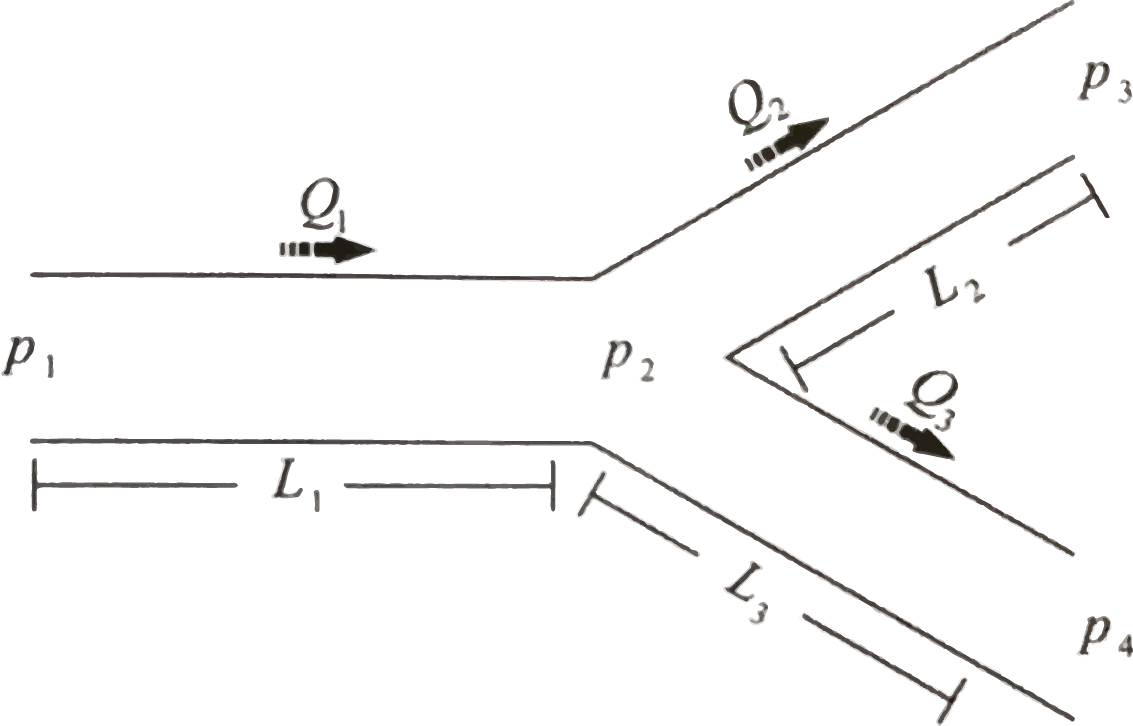

You are interested in determining the flow rates through each fluidic segment. From you (to be completed, future) engineering coursework, you know that you can describe this system as incompressible flow using Hagen-Poiseuille relations incorporating the equivalent hydraulic resistance. In this system, the hydraulic resistance of channel segment can be defined as follows:

                    
$$R_i =\frac{8\eta L}{\pi R^4 }$$


**Step 1: write down the physical parameters you know and draw a schematic.**

% Known physical parameters in this system
eta = 1*10^-3; %viscosity, Pa*s
L1 = 0.5*10^-2; % m
L2 = 1*10^-2; % m
L3 = 2*10^-2; % m
R = 20*10^-6; % m

% Calculate fluidic resistance of each channel segment
R1 = 8*eta*L1/(pi*R^4)*10^-12;   % kPa*s/mm^3
R2 = 8*eta*L2/(pi*R^4)*10^-12;   % kPa*s/mm^3
R3 = 8*eta*L3/(pi*R^4)*10^-12;   % kPa*s/mm^3

**Step 2: state assumptions and write down equations describing the system**. In this case, we are assuming steady, incompressible flow, yielding the following equations:

                        
$$\begin{array}{l}
p_1 -p_2 =Q_1 R_1 \\
p_2 -p_3 =Q_2 R_2 \\
p_2 -p_4 =Q_3 R_3 
\end{array}$$


Because the system is incompressible, we know from conservation of mass:

                        
$$Q_1 =Q_2 +Q_3$$


In addition, we know the input pressure (perhaps supplied by a pump) and the output pressures (atmospheric pressure):

                        
$$\begin{array}{l}
p_1 =110\;\textrm{kPa}\\
p_3 =100\;\textrm{kPa}\\
p_4 =100\;\textrm{kPa}
\end{array}$$


**Step 3: solve system of equations.** Here, we have 7 variables and 7 equations. We can solve the problem using the matrix representation approach by first writing all of the equations in the form $a_{11} x_1 +a_{12} x_2 +\ldotp \ldotp \ldotp +a_{13} x_3 =c_1$.

                        
$$\begin{array}{l}
p_1 =110\\
p_3 =100\\
p_4 =100\\
p_1 -p_2 -Q_1 R_1 =0\\
p_2 -p_3 -Q_2 R_2 =0\\
p_2 -p_4 -Q_3 R_3 =0\\
Q_1 -Q_2 -Q_3 =0
\end{array}$$


Converting this a matrix (**NOTE: I have taken care to ensure all units are properly matched**):

                        
$$\left\lbrack \begin{array}{ccccccc}
1 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 0 & 0\\
1 & -1 & 0 & 0 & -R_1  & 0 & 0\\
0 & 1 & -1 & 0 & 0 & -R_2  & 0\\
0 & 1 & 0 & -1 & 0 & 0 & -R_3 \\
0 & 0 & 0 & 0 & 1 & -1 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p_1 \\
p_2 \\
p_3 \\
p_4 \\
Q_1 \\
Q_2 \\
Q_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
110\\
100\\
100\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


This can be solved using the matrix division we talked about last time.

                        
$$\mathbf{x}=\mathbf{A}\backslash \textrm{Ax}=\mathbf{A}\backslash \mathbf{b}$$


clear A b   % Clear previously used terms from workspace
% Define matrix A
A(4,1:7)=[1,-1,0,0,-R1,0,0];    % We specify columns 1:7 because the matrix A is not yet defined
A(5,:)=[0,1,-1,0,0,-R2,0];
A(6,:)=[0,1,0,-1,0,0,-R3];
A(7,:)=[zeros(1,4),1,-1,-1];
A([1,16,24]) = 1;               % Use single index notation to specify sparse 1 values
disp(A)

    1.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0
         0         0         0    1.0000         0         0         0
    1.0000   -1.0000         0         0  -79.5775         0         0
         0    1.0000   -1.0000         0         0 -159.1549         0
         0    1.0000         0   -1.0000         0         0 -318.3099
         0         0         0         0    1.0000   -1.0000   -1.0000



% Define matrix b
b = [110,100,100,zeros(1,4)]';  % Note the transpose: we need b to be a column vector
disp(b)

   110
   100
   100
     0
     0
     0
     0



% Solve system of equations
x = A\b;
disp(x)

  110.0000
  105.7143
  100.0000
  100.0000
    0.0539
    0.0359
    0.0180



Thus, in one line of code, we obtain the solution to this set of 7 linear equations. In this case, the solution is as follows.

                        
$$\begin{array}{l}
p_1 =110\;\textrm{kPa}\\
p_2 =106\;\textrm{kPa}\\
p_3 =100\;\textrm{kPa}\;\\
p_4 =100\;\textrm{kPa}\\
Q_1 =0\ldotp 054\;{\textrm{mm}}^3 /\mathrm{s}\\
Q_2 =0\ldotp 036\;{\textrm{mm}}^3 /\mathrm{s}\\
Q_3 =0\ldotp 018\;{\textrm{mm}}^3 /\mathrm{s}
\end{array}$$


*Side challenge*: can you create matrix A, above, in four lines of code or less?

### Functions

Recall: assemblages of code can be composed in the editor window and stored as an .m file for more permanence. These assemblages of code are referred to as either functions or scripts. Functions start with the `function` declaration whereas scripts are just assemblages of statements.

#### Functions vs. scripts

- The following refers to .m files created to contain a function or a script.

            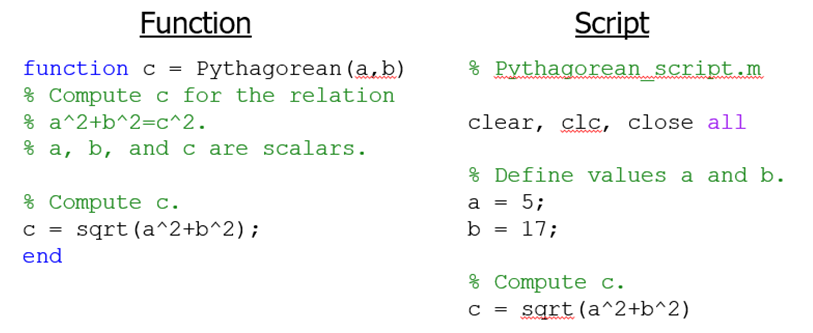

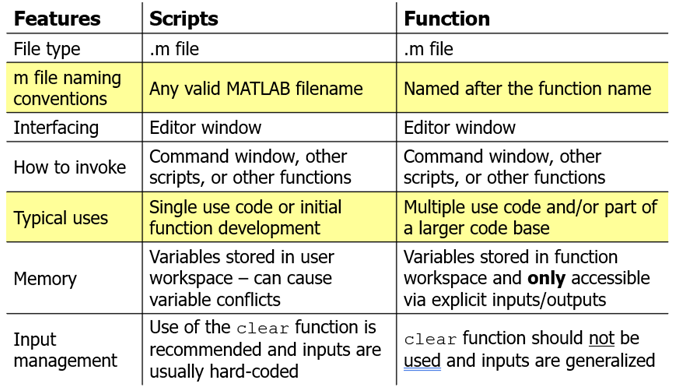

**"Where" do we create functions?**

- To run on the command line, you need to create a function in a new `.m` file.

- When using the LiveScript, each individual function is saved at the end of the` .mlx` document.

#### Examples of function declarations

**Note:** function **declarations **go at the top of a `.m` file and may only be preceded by comments.

- No inputs and no outputs

- One input and one output

- Multiple outputs and no inputs

- Three outputs and two inputs

**NOTE:** the number of inputs does not need to match the number of outputs.

#### Function rules

- When creating an `.m` file to contain the function, name the `.m` file the same as the function name.

- Do not use a variable within a function that has the same name as the function.

- Do not hard-code inputs.

- Use only one function per .m file

- All function outputs should be calculated at some point within the function

- Use `end` at the conclusion of a function.

- For ease of visualizing, indent the contents of a function.

**Do not hard-code inputs.** A poor example of a generalized function

The purpose of a function is to take in variables and manipulate them according to certain rules. The function will always return the same (usually incorrect) result if you redefine the input variables inside the function.

**Variable names only matter to the function.**

- Names matter within a function.

- Order of inputs matters outside the function

% Order of input matters when calling a function
m = 2;
n = 3;
q = 4;
[g1,h1] = myFunction(m,n,q)

g1 = 5

h1 = 12

[g2,h2] = myFunction(q,m,n)

g2 = 6

h2 = 6

**Note:** "**what happens in a function, stays in a function** *(unless passed as an input or output).*" If we were to call `p` or `s`, MATLAB would give an error because those variables are only stored in the local function memory. Unless you specify a variable to be returned as an output, you cannot call it from the command line.

#### Function headers

It is customary to describe the purpose, inputs, outputs, author, and creation/modification date of a function right after the function definition.

It is a best practive to describe units and/or list inputs/outputs with specific descriptions of their assumptions and limitations. In general, **more (clear) information is better**.

- The first line of a function is referred to as the “H1 line” and is searchable by MATLAB using `lookfor.`

- The first contiguous block of text is returned as the help query for the function.

#### Function naming conventions

- Must consist of only the letters a-z, the digits 0-9, and underscores (_)

- Must start with a letter

- The filename of functions should adopt the function name. The following would be saved as `myFunc.m`.

**NOTE:** Camel caps and underscores are easier to distinguish than long strings of lowercase characters

- `piratePathA` and `pirate_path_A` are easier to interpret than `piratepatha`

Programmers often start low level functions with a lowercase character - e.g. `supportFunction` or `doSmallThing`

#### Example

Create a function to output the odd entries of an input vector.

% Define a vector to input into the function
u = linspace(1,10,8)

u =     1.0000    2.2857    3.5714    4.8571    6.1429    7.4286    8.7143   10.0000


% Call the function and store output as variable.
v_odd = returnOddElements(u)

v_odd =     1.0000    3.5714    6.1429    8.7143


#### Example: systems of nonlinear systems of equations

Nonlinear systems have many solution methods based on the nature of the equations and the application. For example, to solve the following set of nonlinear equations.

                    
$$\begin{array}{l}
y^2 =x\\
y=2x^2 -3
\end{array}$$


     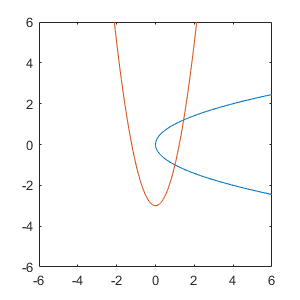

- We can invoke MATLAB's nonlinear equation solver `fsolve()`, which demands equations of the form `F(x,y…)=0`

- Rearranging the equations to this form:

                
$$\begin{array}{l}
y^2 -x=0\\
y-2x^2 +3=0
\end{array}$$


- Renaming the variables for convenience:

                
$$\begin{array}{l}
{x_2 }^2 -x_1 =0\\
x_2 -2{x_1 }^2 +3=0
\end{array}$$


To solve, we first define a function that contains a description of the equations that will eventually be called by `fsolve``()`. 

**Note**: the `0`’s have been replaced by `F`’s and mathematical subscripts have been changed to indexing subscripts

The set of equations can now be solved using `fsolve``()- `this code is contained in a function block in this LiveScript document or in a separate m-file.

- Since we have two valid solutions (which we know because we plotted the functions first), we must call `fsolve``()` twice.

- In each case we will provide different initial guess conditions that promote convergence to the two different solutions.

% Determine solution 1
sol_1 = fsolve(@eqnSet,[0,0])

'fsolve' requires Optimization Toolbox.

Notes on the above code:

- `sol_1:` a 1x2 vector containing the first intersection point (*x*and *y*, respectively).

- `@eqnSet:` the first input into the fsolve(), this tells the function where the equations are located.

- `[0,0]:`the second input in fsolve(), this specifies our initial guess as to where the first intersection is located.

- `fsolve()` will attempt to converge to a solution until some stopping criteria (threshold) is met. 

% Determine solution 2
sol_2 = fsolve(@eqnSet,[1,1])

**NOTE**: the `@` symbol is called a function handle and is a way to pass one function into another function. We will discuss this more later.

**Functions for this LiveScript file are contained below. When creating multiple functions in a LiveScript file, put each in a separate block of code.**

- To be used with line 54

function [p,s] = myFunction(a,b,c)
    % p and s are computed within the function
    p = a+b;
    s = b*c;
end

- Unused, but contained here

function out = mySquareRoot(a)
    % Returns the square root of a scalar, 
    % vector, or multidimensional array
    % input, a, to out
    % M. Siedlik
    % 9/6/2020
             
    % Calculates the square root
    % of the inputout = sqrt(a);
    out = sqrt(a);
end

- To be used with line 63

function out = returnOddElements(v)
    % Select the odd indices of the input vector
    out = v(1:2:end);
end

- To be used with line 65

function F = eqnSet(x)
    % System of two non linear equations
    % F(1) and F(2): "equation" 1 and 2, respectively
    % x(1) and x(2): variable 1 and 2, respectively
    F(1) = x(2)-2*x(1)^2+3;
    F(2) = x(2)^2-x(1);
end